Zerar workspace

clear;

Os dados originais (CSV) devem ter sido tratados previamente (editar a hora para o formato YYYY-MM-DD hh:mm:ss, adicionar linha de cabeçalho, verificar numero de colunas)

Importar CSV dos dados

node1 = readtable('logs/csv/coleta02_20170131_20170207/1/WMLOGB_edited.CSV');
node2 = readtable('logs/csv/coleta02_20170131_20170207/2/WMLOGB_edited.CSV');
node3 = readtable('logs/csv/coleta02_20170131_20170207/3/WMLOGB_edited.CSV');
node4 = readtable('logs/csv/coleta02_20170131_20170207/4/WMLOGB_edited.CSV');

Ajustando dados do sensor 03 do nó 4 (multiplicando por -1 para tornar os valores positivos)

node4.sensor03value = node4.sensor03value * -1;
node4.sensor03value = median(node4{1:end,53:74},2,'omitnan');

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizando a formula que leva em consideração a temperatura do solo)

*Detalhe: a temperatura utilizada não é do solo, mas do sensor RTC*

% wmlog_node1.sensor01cbar = (3.213*(wmlog_node1.sensor01value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor01value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor02cbar = (3.213*(wmlog_node1.sensor02value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor02value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor03cbar = (3.213*(wmlog_node1.sensor03value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor03value./1000)-0.01205*wmlog_node1.temperature)

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizanda a fórmula básica de conversão da irrometer)

node1{:,4:end} = (node1{:,4:end}-550)./137.5;
node2{:,4:end} = (node2{:,4:end}-550)./137.5;
node3{:,4:end} = (node3{:,4:end}-550)./137.5;
node4{:,4:end} = (node4{:,4:end}-550)./137.5;

**TESTE: **ajustes de escala (nós 1 e 2 estão em uma ordem de grandeza maior, não sei o motivo)

node1{:,4:end} = node1{:,4:end}/100;
node2{:,4:end} = node2{:,4:end}/100;

**FIXME: verificar se a redução a seguir é mesmo necessária**

Segundo a documentação dos sensores watermark irrometer, eles foram calibrados para funcionar a 70ºF. A cada grau F acima de 70 é necessário reduzir a leitura em 1%

Considerando o solo a 32ºC (89.6ºF)

soil_temp = 89.6;
sensor_adjustment = (100 - (soil_temp - 70))/100;

node1{:,4:end} = node1{:,4:end} * sensor_adjustment;
node2{:,4:end} = node2{:,4:end} * sensor_adjustment;
node3{:,4:end} = node3{:,4:end} * sensor_adjustment;
node4{:,4:end} = node4{:,4:end} * sensor_adjustment;

 Extrair os valores das medições (ex.: raw 1 a raw 22 para o primeiro sensor)

node1sensor1 = node1{:,6:27};
% node1sensor2 = node1{:,29:51};
% node1sensor3 = node1{:,53:end};

node2sensor1 = node2{:,6:27};

node3sensor1 = node3{:,6:27};

node4sensor1 = node4{:,6:27};

Converter de colunas para linhas

node1sensor1 = node1sensor1';
% node1sensor2 = node1sensor2';
% node1sensor3 = node1sensor3';

node2sensor1 = node2sensor1';

node3sensor1 = node3sensor1';

node4sensor1 = node4sensor1';

Obter as leitura a partir dos valores brutos

FIXME: decidir entre média, mediana, etc

read1 = median(node1sensor1(1:11,:),'omitnan');
read2 = median(node1sensor1(12:22,:),'omitnan');
node1sensor1_bias = norm(read1 - read2);
node1sensor1_avg = (read1 + read2) / 2;
node1sensor1_std = std(node1sensor1,'omitnan');
node1sensor1_var = var(node1sensor1,1,'omitnan');

% read1 = median(node1sensor2(1:11,:),'omitnan');
% read2 = median(node1sensor2(12:22,:),'omitnan');
% node1sensor2_bias = norm(read1 - read2);
% node1sensor2_avg = (read1 + read2) / 2;
% node1sensor2_std = std(node1sensor2,'omitnan');
% node1sensor2_var = var(node1sensor2,1,'omitnan');
% 
% read1 = median(node1sensor3(1:11,:),'omitnan');
% read2 = median(node1sensor3(12:22,:),'omitnan');
% node1sensor3_bias = norm(read1 - read2);
% node1sensor3_avg = (read1 + read2) / 2;
% node1sensor3_std = std(node1sensor3,'omitnan');
% node1sensor3_var = var(node1sensor3,1,'omitnan');

%%% NODE 2
read1 = median(node2sensor1(1:11,:),'omitnan');
read2 = median(node2sensor1(12:22,:),'omitnan');
node2sensor1_bias = norm(read1 - read2);
node2sensor1_avg = (read1 + read2) / 2;
node2sensor1_std = std(node2sensor1,'omitnan');
node2sensor1_var = var(node2sensor1,1,'omitnan');

%%% NODE 3
read1 = median(node3sensor1(1:11,:),'omitnan');
read2 = median(node3sensor1(12:22,:),'omitnan');
node3sensor1_bias = norm(read1 - read2);
node3sensor1_avg = (read1 + read2) / 2;
node3sensor1_std = std(node3sensor1,'omitnan');
node3sensor1_var = var(node3sensor1,1,'omitnan');

%%% NODE 4
read1 = median(node4sensor1(1:11,:),'omitnan');
read2 = median(node4sensor1(12:22,:),'omitnan');
node4sensor1_bias = norm(read1 - read2);
node4sensor1_avg = (read1 + read2) / 2;
node4sensor1_std = std(node4sensor1,'omitnan');
node4sensor1_var = var(node4sensor1,1,'omitnan');

Plotar gráfico do sensor e do desvio padrão

% errorbar(node1sensor1_avg,node1sensor1_std);
% errorbar(nodesensor2_avg,node1sensor2_std);
% errorbar(node1sensor3_avg,node1sensor3_std);

% errorbar(node2sensor1_avg,node2sensor1_std);

% errorbar(node3sensor1_avg,node3sensor1_std);

% errorbar(node4sensor1_avg,node4sensor1_std);

# Realizando a fusão dos dados utilizando filtro de kalman

## Prê

TEMP: equilibrando o tamanho das matrizes

% node1sensor1(:,122:end) = [];
node1sensor1_avg(:,122:end) = [];
% node2sensor1(:,122:end) = [];
node2sensor1_avg(:,122:end) = [];
% node3sensor1(:,122:end) = [];
node3sensor1_avg(:,122:end) = [];
% node4sensor1(:,122:end) = [];
node4sensor1_avg(:,122:end) = [];

## Parâmetros

Biases #FIXME: falta deteminar o bias de cada um dos sensores

BIAS1 = +1;
BIAS2 = -1;
BIAS3 = 0;
BIAS4 = 0;

Covariância do ruídos das medições *#FIXME: falta atualizar esses valores. Utilizando os valores do exemplo.*

R1 = 0.4;
R2 = 0.2;
R3 = 0.6;
R4 = 0.6;

Covariância do ruído do processo *#FIXME: falta** atualizar esse valor. Utilizando o valor do exemplo.*

Q = .005;

Estado do modelo de transição. Como o estado anterior não é conhecido então se inicia em 1

A = 1;

Modelo de observação (qual o grau de influencia dos dados do sensores na estimativa dos dados. Max: 1)

C1 = 1;
C2 = 1;
C3 = 1;
C4 = 1;

## Realizar a fusão (código de exemplo)

Aplicar o filtro de kalman com um único sensor e plotar gráfico

% xhat = kalman(node1sensor1_avg, A, C1, R1, Q);

Plotar os dados sensoriados puros e os valores estimados #FIXME: verificar pq não há diferença entre esses dois gráficos

% clf % clear current figure window
% plotsigs(1, node1sensor1_avg, xhat, 'Sensor 1')
% title('One sensor: signal cleanup')

Plotar os valores sensoriados normalizados (*cleanup*) e os valores estimados

% plotsigsrms('One sensor', 2, node1sensor1_avg, xhat)

Aplicar o filtro de kalman em dois sensores e plotar gráfico

% xhat = kalman([node1sensor1_avg; node2sensor1_avg], A, [C1; C2], [R1 0; 0 R2], Q);
% plotsigsrms('Dois sensores', 3, node1sensor1_avg, xhat)

## Realizar a fusão (código efetivo)

Uso do filtro de kalman com um sensor

sensor1fused = kalman([node1sensor1_avg], A, [C1], [R1], Q);

Plotar gráfico

subplot(2,2,1)
hold on
plot(sensor1fused,'DisplayName','fused data','LineWidth',4)
plot(node1sensor1_avg,'DisplayName','node1sensor1_avg')
legend('show','Location','northwest')
hold off

Fusão de 2 sensores

sensor1fused = kalman([node1sensor1_avg; node2sensor1_avg],...
    A, [C1; C2], [R1 0; 0 R2;], Q);

Plotar gráfico

subplot(2,2,2)
hold on
plot(sensor1fused,'DisplayName','fused data','LineWidth',4)
plot(node1sensor1_avg,'DisplayName','node1sensor1_avg')
plot(node2sensor1_avg,'DisplayName','node2sensor1_avg')
legend('show','Location','northwest')
hold off

Fusão de 3 sensores

sensor1fused = kalman([node1sensor1_avg; node2sensor1_avg; node3sensor1_avg], A, [C1; C2; C3], [R1 0 0; 0 R2 0; 0 0 R3], Q);

Plotar gráfico

subplot(2,2,3)
hold on
plot(sensor1fused,'DisplayName','fused data','LineWidth',4)
plot(node1sensor1_avg,'DisplayName','node1sensor1_avg')
plot(node2sensor1_avg,'DisplayName','node2sensor1_avg')
plot(node3sensor1_avg,'DisplayName','node3sensor1_avg')
legend('show','Location','northwest')
hold off

Fusão de 4 sensores

sensor1fused = kalman([node1sensor1_avg; node2sensor1_avg; node3sensor1_avg; node4sensor1_avg], ...
    A, [C1; C2; C3; C4], [R1 0 0 0; 0 R2 0 0; 0 0 R3 0; 0 0 0 R4], Q);

Plotar gráfico

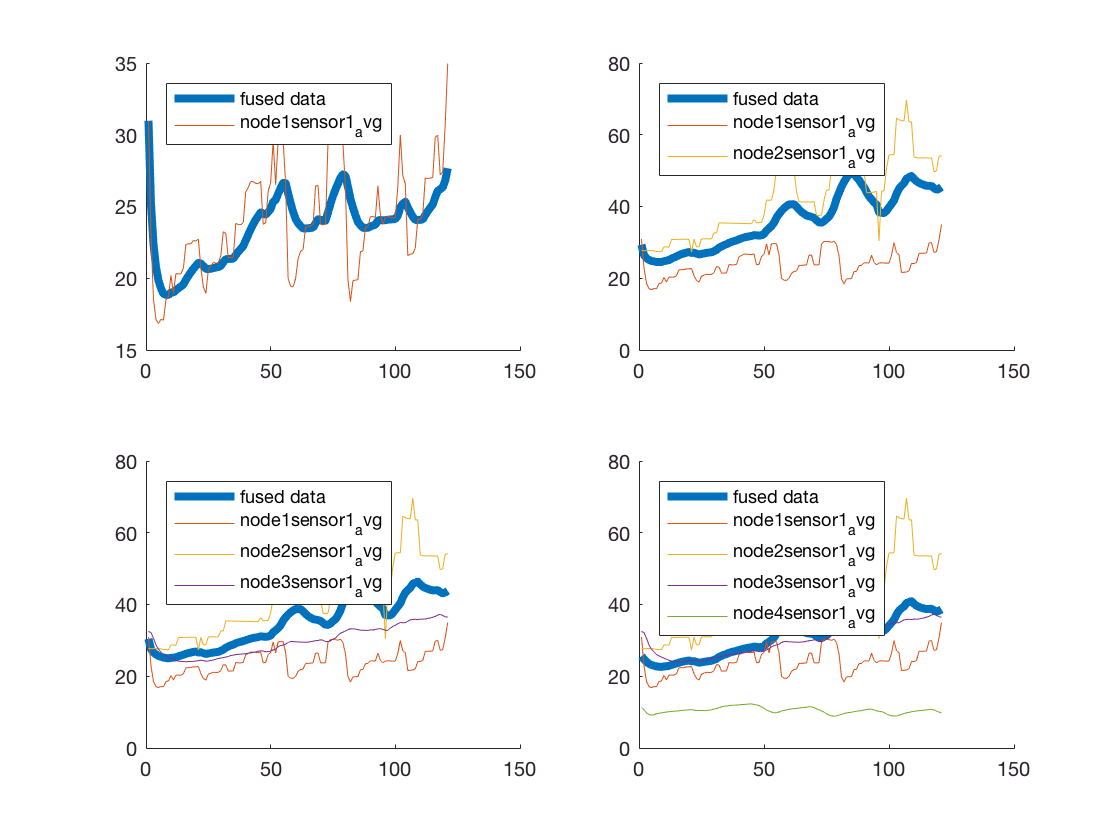

subplot(2,2,4)
hold on
plot(sensor1fused,'DisplayName','fused data','LineWidth',4)
plot(node1sensor1_avg,'DisplayName','node1sensor1_avg')
plot(node2sensor1_avg,'DisplayName','node2sensor1_avg')
plot(node3sensor1_avg,'DisplayName','node3sensor1_avg')
plot(node4sensor1_avg,'DisplayName','node4sensor1_avg')
legend('show','Location','northwest')
hold off

## Funções

function plotsigs(pos, sig1, sig2, sig1label)
subplot(3,1,pos)
hold on
plot(sig1, 'k')
plot(sig2, 'r')
legend({sig1label, 'Estimated'})
ylim([15 40])
hold off
end

function plotsigsrms(label, pos, x, xhat)
plotsigs(pos, x, xhat, 'Actual')
title(sprintf('%s: RMS error = %f', label, sqrt(sum((x-xhat).^2)/length(x))))
end